clear all;

## Onset Conditions

dimension:

N=20;
% correlation paramter:
eta=0;% 1 is symmetric
% amplitude
JAmp=1;
% Sparsity of J
Mdensity=0;
% Tot time 
tot_time=200;
% Delta t:
Dt=0.5;
% Temperature: Increase it!!!
T=0.01;
% Initialise
J=zeros(N,N);
%x=zeros(N,N_tot);
% ICs
var_ICs_X=0.01;
x=var_ICs_X*randn(N,1);
M=sum(x(:,1).^2);
% Fix the constraint sum x^2=N for all t
x(:,1)=x(:,1)*sqrt(N)/sqrt(M);

## Generate Random Matrix:

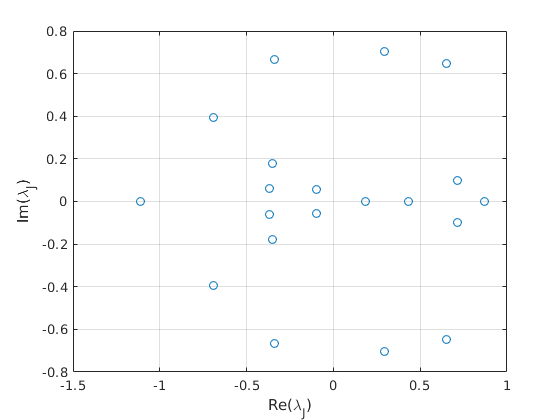

if eta==0
    J=JAmp/sqrt(N)*randn(N);   
 % In case you want sparse:  
 % J=JAmp/sqrt(n)*sprandn(n,n,Mdensity);
J=J-diag(diag(J));
else
    a=sqrt(1-eta^2);
    a=sqrt((1-a)/2);
    b=eta/(2*a);    
    J=JAmp/sqrt(N)*randn(N);    
 % In case you want sparse:  
 % J=JAmp/sqrt(n)*sprandn(n,n,Mdensity);
    J=a*J+b*J';
    J=J-diag(diag(J));
end;
figure;
plot(real(eig(J)),imag(eig(J)),'o');hold on;grid on;
xlabel('Re(\lambda_J)');
ylabel('Im(\lambda_J)')

%hold on;

## n multiple $\Delta$

clear store_mu
clear store_mu_thr
clear err_mu_thr
clear store_diff
clear err
clear X
clear store_f2
clear store_xf
%time steps are generated as Dt*2^-i for i \in {2,.. 14}
Dt=0.1;
dt_s=Dt./(2.^(1:10));
%clear mean_diff
%clear std_diff
for i=1:length(dt_s)
        [mu_thr,mu,f2,xf]=constrain_step2(dt_s(i),x,J,N,T,tot_time);
        store_f2(i)=mean(f2);
        store_xf(i)=mean(xf.^2);
        store_mu_thr(i)=mean(mu_thr);
        store_mu(i)=mean(mu);
        err_mu(i)=std(mu);
        err_mu_thr(i)=std(mu_thr);
        err(i)=std((mu-mu_thr));
        store_diff(i)=mean((mu-mu_thr));
        
end

Undefined function 'constrain_step2' for input arguments of type 'double'.

%save('timestep','mean_diff','std_diff')


figure()
%semilogx(Dt./(2.^(1:10)),(store_mu-store_mu_thr)./(Dt./(2.^(1:10))),'o')
hold on
errorbar(dt_s,(store_mu-store_mu_thr)./dt_s, err./dt_s./sqrt(tot_time./dt_s),'o')

set(gca,'XScale','log')
plot(xlim(),[T-T/N,T-T/N],'--')
xlabel('\Delta t','Fontsize',18)
ylabel('\langle\Delta\mu\rangle','Fontsize',18)
l={'Simulation','Line: \langle\Delta\mu\rangle=T(1-1/N)'}
legend(l,'Location','northwest','FontSize',18)

tightfig(gcf)
hold off
%print('delta_mu_over_timestep','-deps')

## run multiple Temperatures

clear std_diff
clear difference
clear X
clear T_s
clear err
clear store_diff
%time steps are generated as Dt*2^-i for i \in {2,.. 14}
T=0.5;
dt=Dt/(2^6);
T_s=T./(2.^(1:20))
for i=1:length(T_s)
       [mu_thr,mu]=constrain_step(dt,x,J,N,T_s(i),tot_time);
       store_diff(i)=mean(mu-mu_thr);
       err(i)=std((mu-mu_thr));
    %mean_diff(i)=mean(mu-mu_thr);
    %std_diff(i)=std(mu-mu_thr);
end

%save('temperatures','mean_diff','std_diff')



%loglog(T./(2.^(1:14)),store_diff/dt,'o')
errorbar(T_s,store_diff/dt,err/dt/sqrt(tot_time/dt),'o')
hold on
xlabel('T','Fontsize',18)
ylabel('\langle\Delta\mu\rangle','Fontsize',18)
set(gca,'XScale','log','YScale','log')
t=T_s;
ylin=t-t/N
plot(t,ylin,'--')
plot([0.01,0.01],ylim(),'r-.')
text(0.012,1e-5,'T=0.01','Color','r','FontSize',16)

l={'Simulation','Line: \langle\Delta\mu\rangle=T(1-1/N)'}
legend(l,'Location','northwest','FontSize',18)
hold off
xlim([min(t)*0.5,.5])
ylim([5*1e-6,4*1e-1])
tightfig(gcf)
hold off
%print('delta_mu_over_T','-deps')
